Sanusi Isiaka Olatunji

m12435020

## 2a. Load and preprocess datasets in a loop.


path = uigetdir(cd, 'Select the source of the data');
files = dir(path);
nrFiles = length(files);

% Preallocate storage for results
results_matrix = [];
heatmap_data = [];


for i = 3:nrFiles
    fileName = files(i).name;
    filePath = files(i).folder;

    fullFileName = fullfile(filePath, fileName);
    load(fullFileName);

     % Convert to matrix
    dataMat = dataTT{:,:};
    % Extract time and channel names
    timeVec = dataTT.Properties.RowTimes;
    channelNames = dataTT.Properties.VariableNames;

    rowsWithNans = sum(isnan(dataMat),2);
    dataMat(rowsWithNans>0, :) = [];

    % Compute correlations
    lower_corr = corrcoef( dataMat(:, 1),  dataMat(:, 4));
    upper_corr = corrcoef( dataMat(:, 2),  dataMat(:, 3));

    % Store correlation results
    results_matrix = [results_matrix; lower_corr(1, 2), upper_corr(1, 2)];

    % Collect heatmap data (e.g., first channel histogram counts)
    heatmap_data = [heatmap_data; histcounts( dataMat(:, 1), 50)];
end
disp(results_matrix);

    0.9454    0.9220
    0.9563    0.9398
    0.9492    0.6967
    0.9854    0.9484
    0.9216    0.8841
    0.9634    0.9493
    0.9477    0.9406
    0.9798    0.9573
    0.9794    0.9485
    0.9515    0.9057
    0.9600    0.9525
    0.9785    0.9092
    0.8775    0.8075
    0.9710    0.9257
    0.9544    0.9330
    0.9657    0.9498
    0.7949    0.8937
    0.8332    0.8295
    0.9024    0.9287
    0.9420    0.9395
    0.9054    0.8894
    0.9234    0.9295
    0.9211    0.8534
    0.9168    0.8515
    0.9014    0.7365
    0.8230    0.8353
    0.7123    0.9086
    0.9278    0.9412
    0.8774    0.8820



disp(heatmap_data);

          12          68         453         970        1525         968         901         819         635         199         415        1223        1989        2855        1215        1303        1843        1932        1542        3328        4665        4926        6404        4656        4914        5790        4301        3548        1734        1197         887         780         896         737        1311        1636        2173        2598        2207         905         660         470         599        1859        1084         266         377         262          87         276
         132         571         421         583         529         807         526         385         565        1380        3002        1920        3723        4565        6926        6300        3711        3701        3279        5436        4891        8173        5271        3964        3826        2326         762         508         824        1440        1004        1154         881   

## 2b. Plot the correlation results.

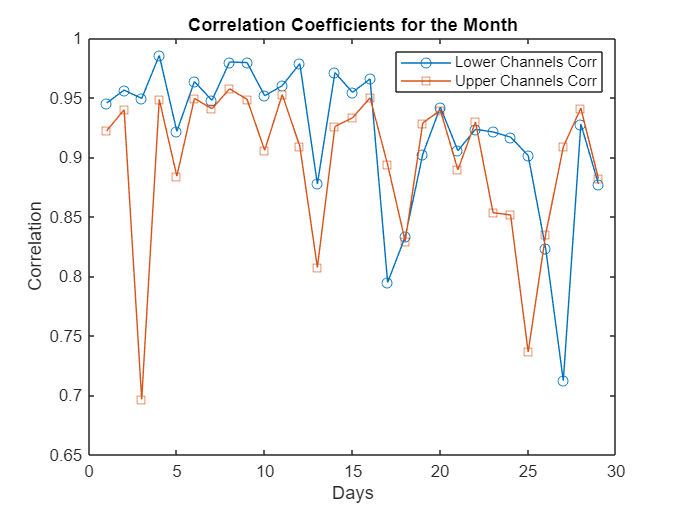

% Plot correlations
figure;
plot(results_matrix(:, 1), '-o', 'DisplayName', 'Lower Channels Corr');
hold on;
plot(results_matrix(:, 2), '-s', 'DisplayName', 'Upper Channels Corr');
title('Correlation Coefficients for the Month');
xlabel('Days');
ylabel('Correlation');
legend show;

2c. **Interpret the correlation results.**A high correlation indicates similar behavior between channels, while fluctuations reflect varying synchronization levels over time.

## 2d. Plot a heatmap for the first channel.

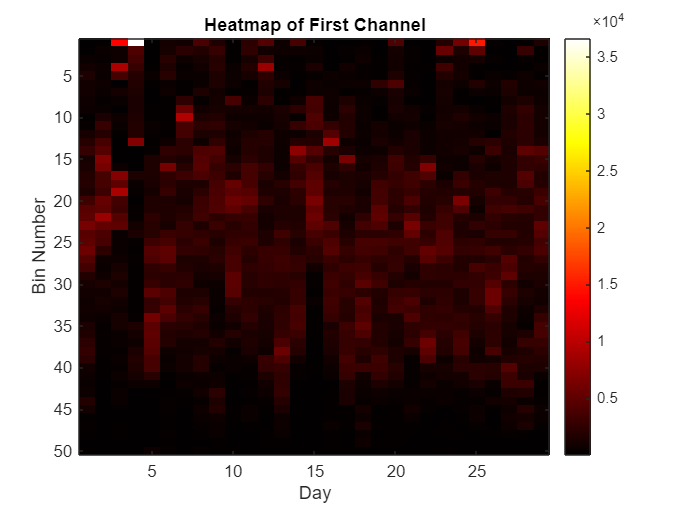

% Plot heatmap
figure;
imagesc(heatmap_data');
colormap('hot');
colorbar;
title('Heatmap of First Channel');
xlabel('Day');
ylabel('Bin Number');